%Ex01
X1 = [1 1];
X2 = [1 0 1];

%a)
[R, P, K] = residue(X1, X2);

%b)
syms s t
X = (s + 1)/(s^2 + 1);
F1 = R(1)/(s-P(1));
F2 = R(2)/(s-P(2));
x1 = ilaplace(F1+F2, t)

$$x1 = {\mathrm{e}}^{-t\,\mathrm{i}}\,\left(\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right)+{\mathrm{e}}^{t\,\mathrm{i}}\,\left(\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right)$$

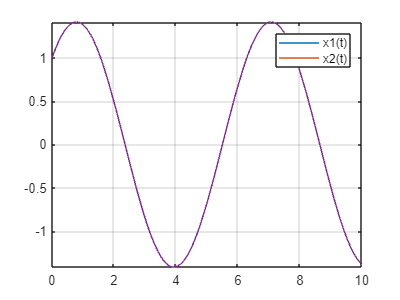

x2 = ilaplace(X);

%c)
fplot(x1, [0 10])
hold on 
fplot(x2, [0 10])
grid on
legend('x1(t)', 'x2(t)')

%Ex02
syms Y
y = laplace(Y, s)

$$y = \frac{1}{s^{2}}$$

$$dy = \frac{1}{s}$$

$$d2y = 0$$